## ECE 537 : Assignment 6

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;
rng('default')

**Task 1: **Load the Exercise 7 Data Set, which consists of drawn data from two classes. For the first measurement feature vector apply an appropriate statistical goodness-of-fit test to determine whether or not the this feature is Gaussian.

**Solution:**

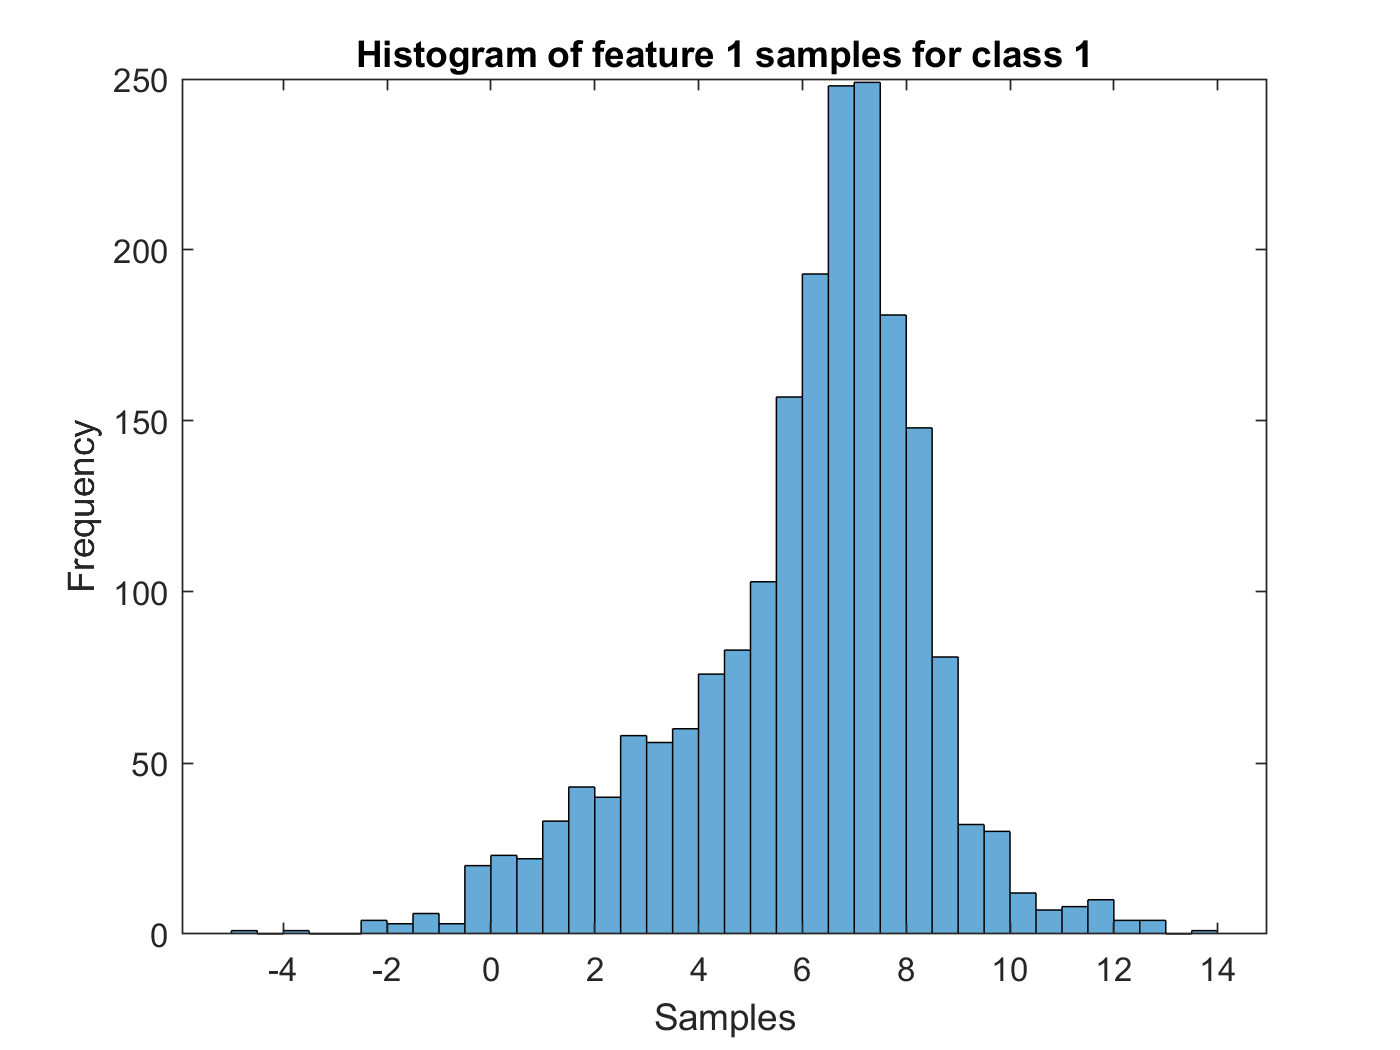

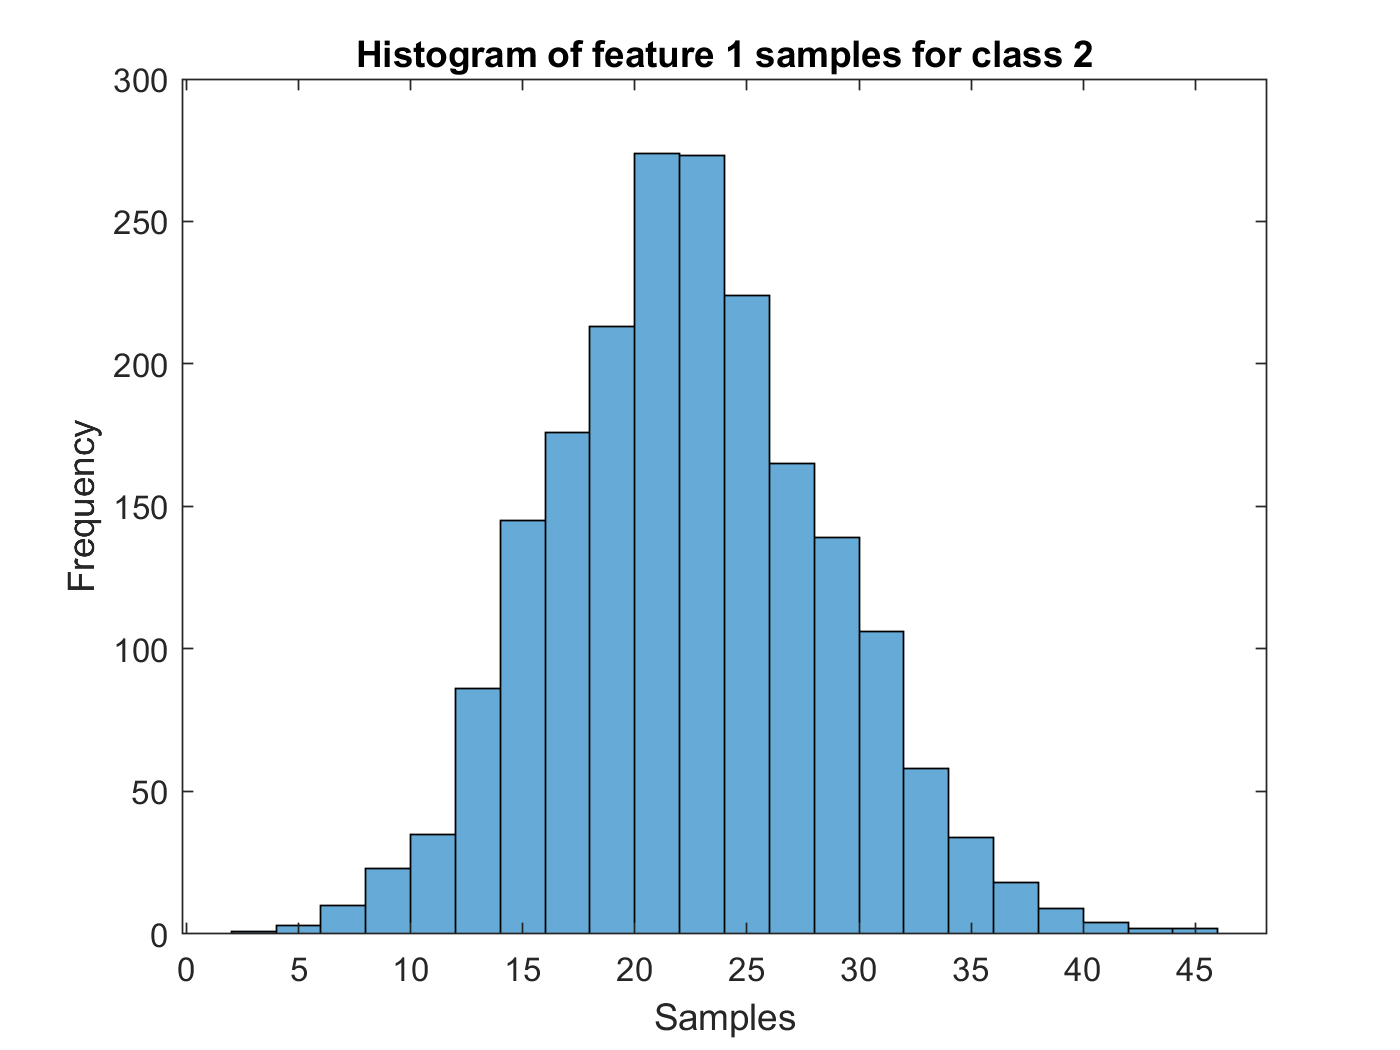

load('Exercise_7_data.mat')
u = unique(class);
[data_class, F1,F2,h1,h2] = deal(cell(2,1));
for i = 1:length(u)
    figure(i)
    data_class{i} = data(class==u(i),:);
    F1{i}  = data_class{i}(:,1);
    h1{i} = chi2gof(F1{i}) ;
    figure(i)
    histogram(F1{i});
    xlabel('Samples')
    ylabel('Frequency')
    title(sprintf('Histogram of feature 1 samples for class %i',i))
end

**Comments**: Using the chi-squared goodness of fit test which tests the null hypothesis that the data in F1 comes from a normal distribution with mean and varriance estimated from F1. For Class 1 The test returns an h value of 1 which indicates that it has rejected the null hypothesis and the data is not normally distributed. For Class 2 The test returns an h value of 0 which indicates that it has accepted the null hypothesis and the data is  normally distributed. Based on the histogram of the data in Class 1 F1 the data seems to be drawn from an exponential distribution.

**Task 2: **Determine the Bayes classification error rate for the data if the analysis is based solely on data taken from the first measurement feature. Note you can no longer simply assume that the data for each class is Gaussian distributed. Moreover, Bayes classification does not make this assumption but, instead applied generally to any class distribution

figure(2)
minF1 = min(F1{1});
maxF1 = max(F1{1});
minF2 = min(F1{2});
maxF2 = max(F1{2});

%Likelihood with mvksdensity
[pxwA,~] = mvksdensity(F1{1},data(:,1),'bandwidth',0.8);
[pxwB,~] = mvksdensity(F1{2}, data(:,1),'bandwidth',0.8);
pwA = nnz(class == 0)/length(class);
pwB = nnz(class == 1)/length(class);
% % muB = mean(F1{2});
% % sigmaB = cov(F1{2});
% 
% % %likelihood
% % pxwB = gaussian_density(muB,sigmaB,data(:,1)); %gaussian density

%evidence
px = pxwA*pwA + pxwB*pwB; %evidence

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);


%visualization

[~,class_index] = max([gA gB],[],2);
error = nnz(class_index-1 - class')/length(class);
fprintf('The Bayes error rate using Feature 1 for classification is %0.2f %%', 100*error)

The Bayes error rate using Feature 1 for classification is 2.00 %

Notes:

High mutual information among several features, Certain classification information is duplicated across more features, it would weight these features more since we are counting more. If mutual infromation is present, there is mapping between different features  linear and non linear and then we over count the countribution of specific infromation. 

**Task 3: **Determine the Bayes classi�cation error rate for the data if the analysis is based solely on data taken from the second measurement feature.

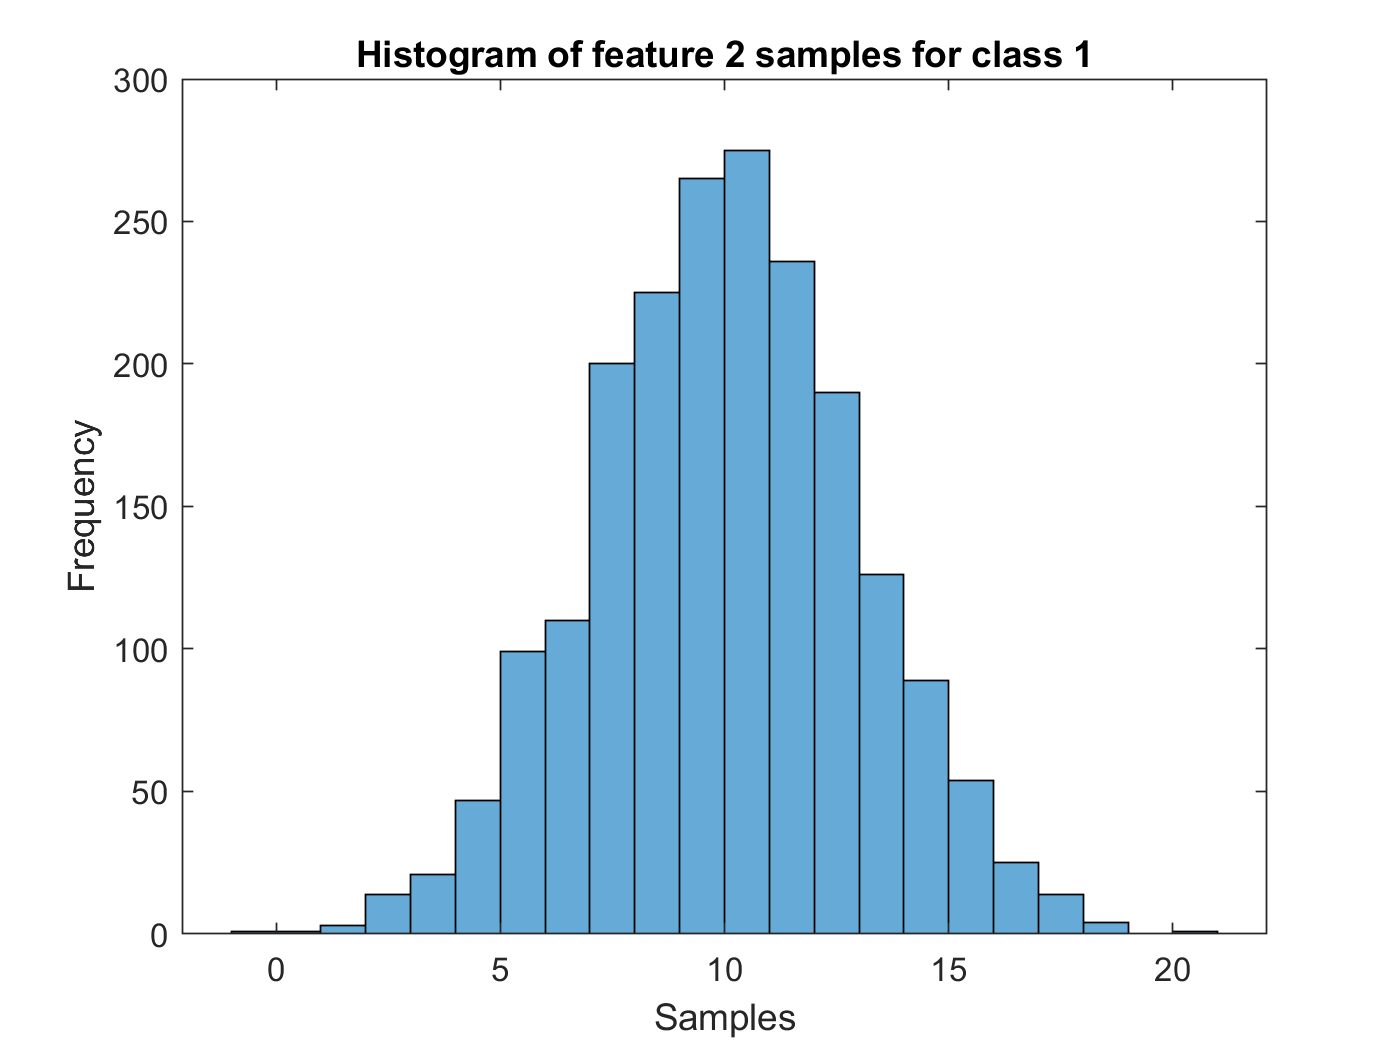

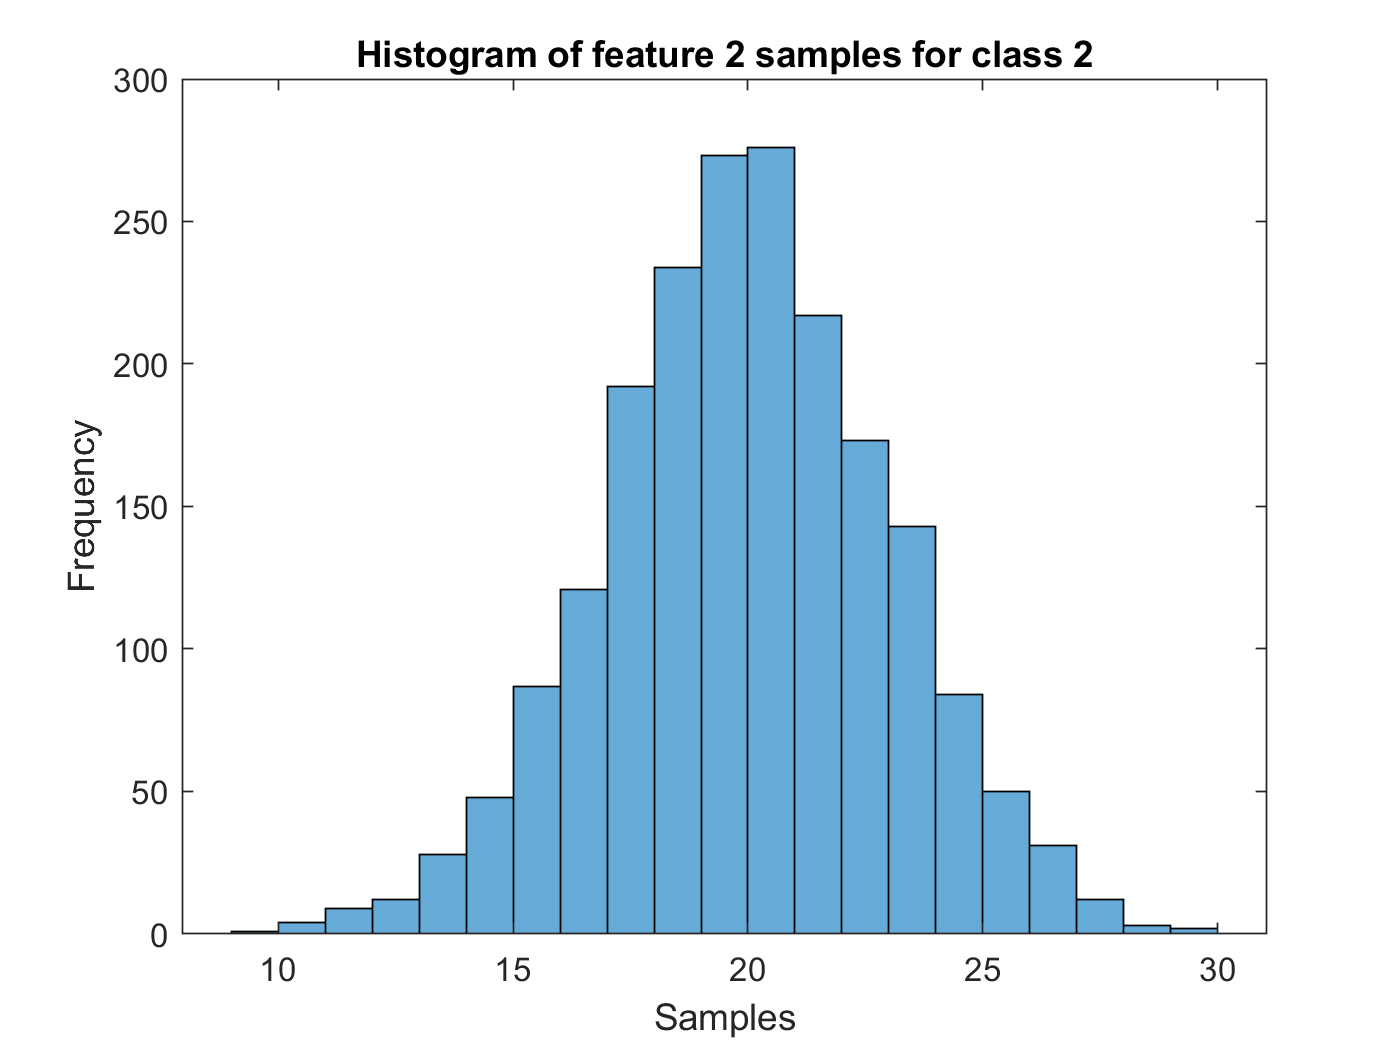

for i = 1:length(u)
    figure(i+2);
    F2{i}  = data_class{i}(:,2);
    h2{i} = chi2gof(F2{i});
    histogram(F2{i})
    xlabel('Samples')
    ylabel('Frequency')
    title(sprintf('Histogram of feature 2 samples for class %i',i)) 
end

%Likelihood with mvksdensity
[pxwA,~] = mvksdensity(F2{1},data(:,2),'bandwidth',0.8);
[pxwB,~] = mvksdensity(F2{2}, data(:,2),'bandwidth',0.8);
pwA = nnz(class == 0)/length(class);
pwB = nnz(class == 1)/length(class);
px = pxwA*pwA + pxwB*pwB; %evidence

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);


%visualization

[~,class_index] = max([gA gB],[],2);
error = nnz(class_index-1 - class')/length(class);
fprintf('The Bayes error rate using Feature 2 for classification is %0.2f %%', 100*error)

The Bayes error rate using Feature 2 for classification is 4.95 %

**Task 4: **Determine the Bayes classifcation error rate for the data if the analysis is based on all of the available measurement features, where you will also need to apply proper data normalization.

Solution:

%Normalization 


function [gA gB, class_index] = bayes_classifier(train_data,train_labels,test_data,test_labels)
class_A_train = train_data(train_labels==1,:);
mu_A = mean(class_A_train);
sigma_A = cov(class_A_train);
class_B_train = train_data(train_labels==2,:);
mu_B = mean(class_B_train);
sigma_B = cov(class_B_train);
%priori probabilities
pwA = nnz(train_labels==1)/length(train_labels);
pwB = nnz(train_labels==2)/length(train_labels);


%likelihood
pxwA = gaussian_density(mu_A,sigma_A,test_data);
pxwB = gaussian_density(mu_B,sigma_B,test_data);

%evidence
px = pxwA*pwA + pxwB*pwB; %evidence

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);


%visualization

[~,class_index] = max([gA gB],[],2);

end 

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

